**System 5**

load('PS1.mat')
n=13;%A01636406
A1=A1(n);
A2=A2(n);
Ref_1=Ref_1(n);
Ref_2=Ref_2(n);
H1max=H1max(n);
H2max=H2max(n);
MyVariable=DataID{n}

MyVariable =          0         0
    0.0085    0.3990
    0.0169    1.5176
    0.0254    3.2044
    0.0339    5.2769
    0.0423    7.5382
    0.0508    9.7941
    0.0593   11.8677
    0.0677   13.6120
    0.0762   14.9189


R1=R1(n);
R2=R2(n);
Qin_1=Qin_1(n);
Qin_2=Qin_2(n);
b=8;

**Transfer Functions**

H1=tf([R1],[A1*R1 1])

H1 =
 
     2.9
  ----------
  63.8 s + 1
 
Continuous-time transfer function.



H2=tf([R2], [A1*A2*R1*R2 ((A2*R2)+(A1*R1)) 1])

H2 =
 
           3.7
  ----------------------
  9206 s^2 + 208.1 s + 1
 
Continuous-time transfer function.



**H1 Lead Compensator**

%sisotool(H1)
Ess5_H1=b/100;
kG5_H1=R1

kG5_H1 = 2.9000

kC5_H1=(1-Ess5_H1)/(Ess5_H1*kG5_H1)

kC5_H1 = 3.9655

xG5_H1=-1;
yG5_H1=-2;
zG5_H1=(yG5_H1*kC5_H1)/xG5_H1

zG5_H1 = 7.9310

C5_H1=zpk([xG5_H1],[yG5_H1],[zG5_H1])

C5_H1 =
 
  7.931 (s+1)
  -----------
     (s+2)
 
Continuous-time zero/pole/gain model.



**H2 Lead Compensator**

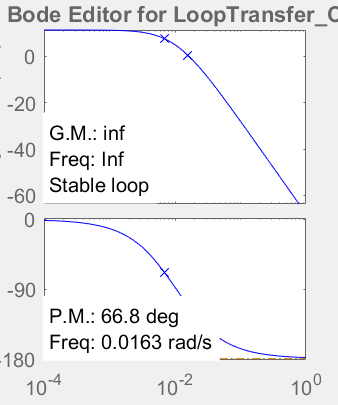

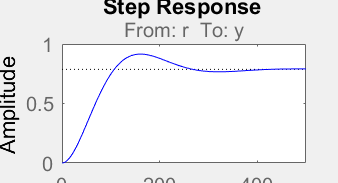

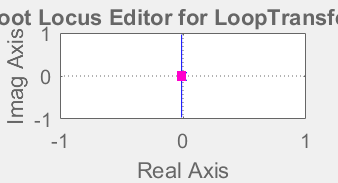

sisotool(H2)

Ess5_H2=b/100;
kG5_H2=R2

kG5_H2 = 3.7000

kC5_H2=(1-Ess5_H2)/(Ess5_H2*kG5_H2)

kC5_H2 = 3.1081

xG5_H2=-1;
yG5_H2=-2;
zG5_H2=(yG5_H2*kC5_H2)/xG5_H2

zG5_H2 = 6.2162

C5_H2=zpk([xG5_H2],[yG5_H2],[zG5_H2])

C5_H2 =
 
  6.2162 (s+1)
  ------------
     (s+2)
 
Continuous-time zero/pole/gain model.



**H2 Lead-Lag Compensator**

EssL5=2/100;
%Lead
zG5_LL=0.05;
kG5_LC=R2

kG5_LC = 3.7000

kC5_LC=xG5_H2*zG5_LL/yG5_H2

kC5_LC = 0.0250

C5_LC=zpk([xG5_H2],[yG5_H2],[zG5_LL])

C5_LC =
 
  0.05 (s+1)
  ----------
    (s+2)
 
Continuous-time zero/pole/gain model.




%Lag
kC5_LgC=(1-EssL5)/(EssL5*kG5_LC*kC5_LC)

kC5_LgC = 529.7297

xlg5=-0.2;
ylg5=xlg5/kC5_LgC

ylg5 = -3.7755e-04

C5_LgC=zpk([xlg5],[ylg5],[1])

C5_LgC =
 
     (s+0.2)
  -------------
  (s+0.0003776)
 
Continuous-time zero/pole/gain model.



C5_C=C5_LC*C5_LgC

C5_C =
 
  0.05 (s+1) (s+0.2)
  -------------------
  (s+2) (s+0.0003776)
 
Continuous-time zero/pole/gain model.

